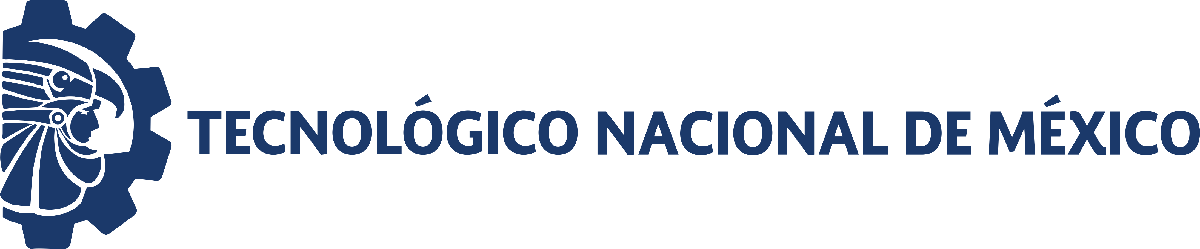                                 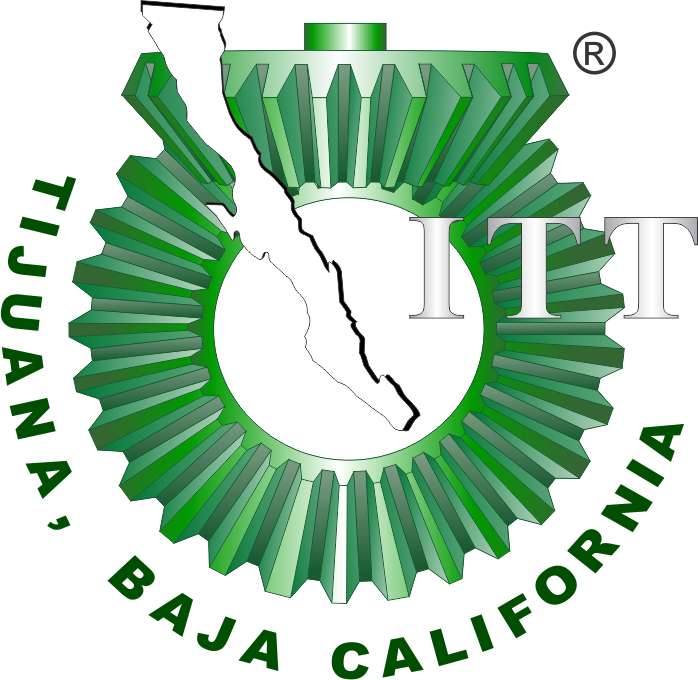

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Proyecto Final

**Objetivo. **El desarrollo del proyecto final tiene como objetivo integrar las competencias específicas relacionadas con el modelizado, análisis y control de sistemas biológicos para ilustrar y predecir su dinámica tanto en el corto como en el largo plazo; esto con el objetivo de sentar las bases para el diseño de gemelos digitales que permitan solucionar problemas relacionados al campo de la Biología de Sistemas.

Para traducir el diagrama y la dinámica biológica al lenguaje algebraico, utilizamos un sistema de Ecuaciones Diferenciales Ordinarias (EDOs) no lineales. Este sistema captura cómo cambia la población de cada tipo celular en el tiempo (t) para la enfermedad del Virus de Inmunodeficiencia Humana (VIH).


$$$$\frac{dx}{dt} = r_1 x + r_2 x y z$$

$$\frac{dy}{dt} = r_3 y - r_4 y z$$

$$\frac{dz}{dt} = r_5 z - r_6 x z$$$$


donde los parámetros son:

x(t) = población de celulas infectadas

y(t) = población de celulas sanas

z(t) = carga viral

r1 = Tasa de proliferación o crecimiento natural de las células infectadas (crecimiento exponencial independiente.

r2 = Tasa de amplificación por interacción. Representa cómo la presencia conjunta del virus (z) y una alta densidad de células sanas (y^2) acelera la generación de nuevas células infectadas (x).

r3 = Tasa de regeneración o crecimiento intrínseco de las células sanas.

r4 = Tasa de infección o mortalidad. Es la proporción de células sanas que son destruidas o transformadas al interactuar o entrar en contacto con el virus (z).

r5 = Tasa de replicación natural, liberación o ingreso del virus al sistema.

r6 = Tasa de aclaramiento o consumo viral. Representa la cantidad de virus libre que desaparece del medio al interactuar con las células ya infectadas (x), ya sea porque se agota al entrar a ellas o por algún mecanismo de competencia.

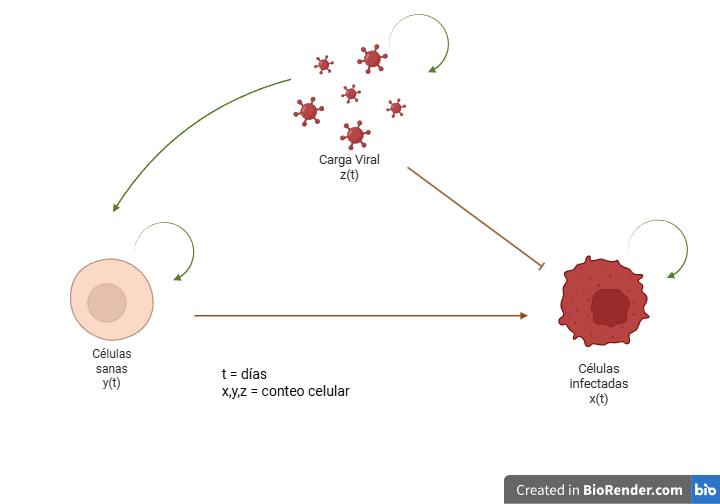 

Figura 1. Sistema de poblaciones celulares.

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

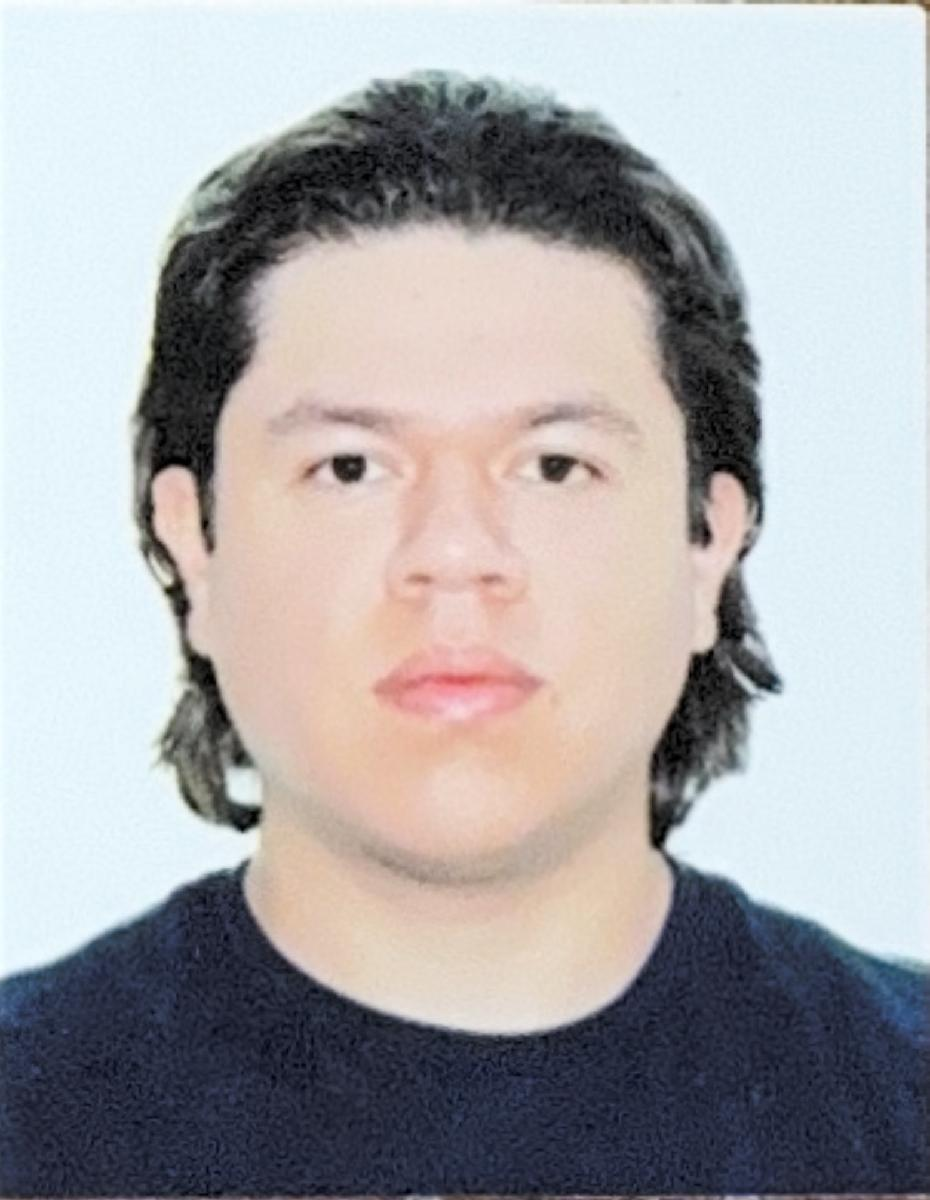 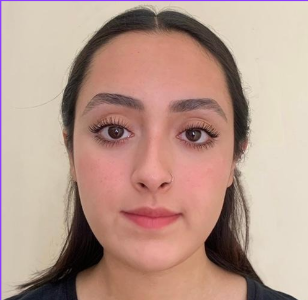

Nombre de los alumnos: Carlos Azael Ramirez Rodriguez; Maria Fernanda Antúnez Rubio

Números de controls: 22212267; 22211745

Correos institucionales: L22212267**@tectijuana.edu.mx; **L22211745**@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

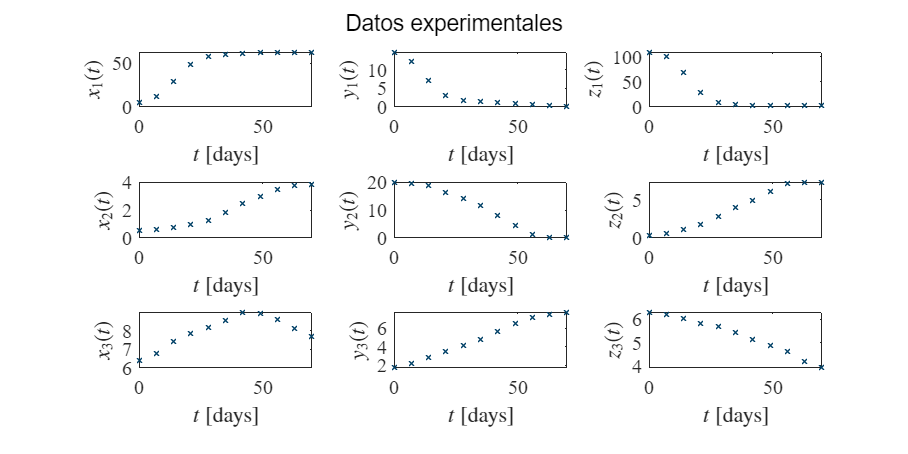

clc; clear; close all; warning('off','all')

[t,x1,y1,z1,x2,y2,z2,x3,y3,z3] = getdata('datos_sistemas_biologicos.csv');
plotsys(t,x1,y1,z1,x2,y2,z2,x3,y3,z3); sgtitle('Datos experimentales');...
    exportgraphics(gcf,'data_raw.pdf','ContentType','vector')

## Procesamiento de datos

### Datos suavizados

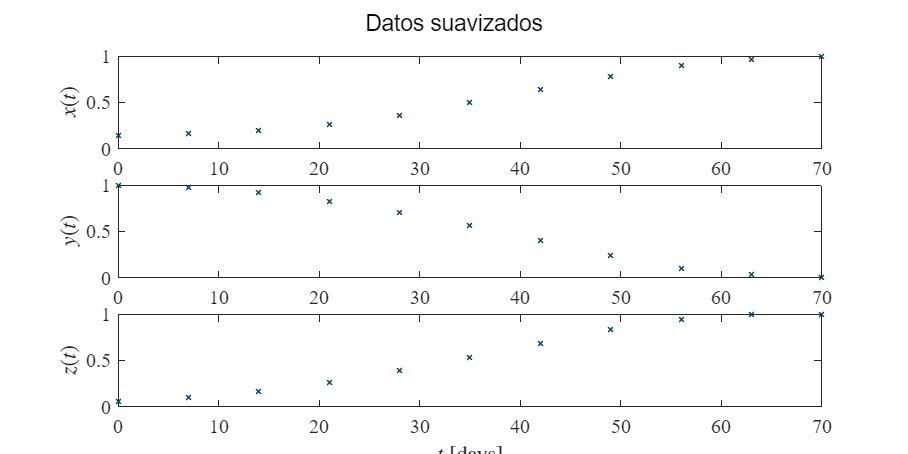

smooth = true; normalize = false;
[to,xo,yo,zo] = getdata2('datos_sistemas_biologicos.csv',smooth,normalize);
plotsys2(to,xo,yo,zo); sgtitle('Datos suavizados');...
    exportgraphics(gcf,'data_smooth.pdf','ContentType','vector')

### Datos normalizados

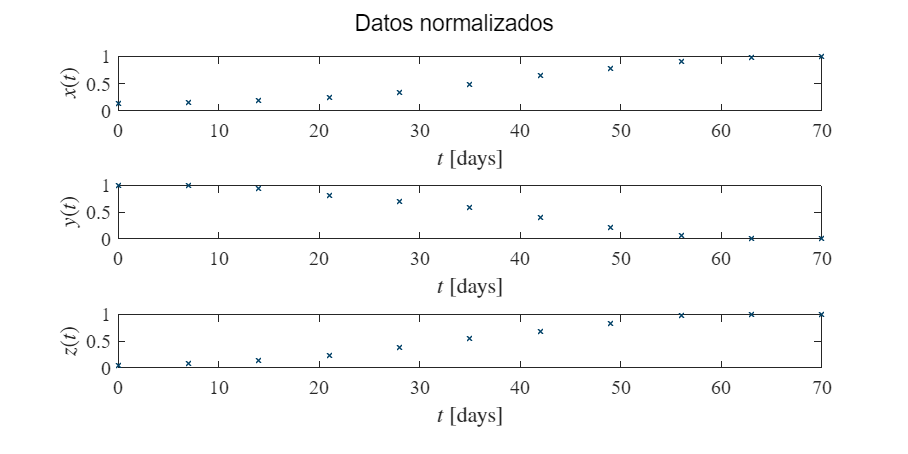

smooth = false; normalize = true;
[to,xo,yo,zo] = getdata2('datos_sistemas_biologicos.csv',smooth,normalize);
plotsys2(to,xo,yo,zo); sgtitle('Datos normalizados');...
    exportgraphics(gcf,'data_normalized.pdf','ContentType','vector')

### Datos suavizados y normalizados

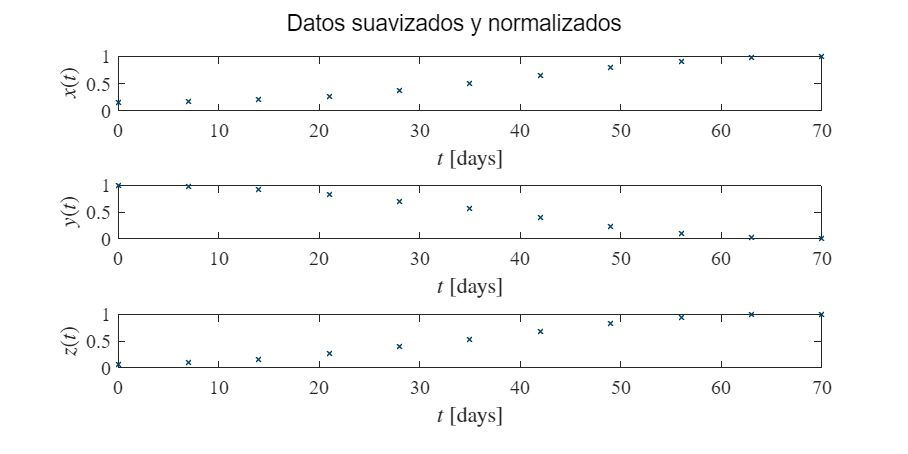

smooth = true; normalize = true;
[to,xo,yo,zo] = getdata2('datos_sistemas_biologicos.csv',smooth,normalize);
plotsys2(to,xo,yo,zo); sgtitle('Datos suavizados y normalizados');...
    exportgraphics(gcf,'data_smooth_normalize.pdf','ContentType','vector');

## Modelo

[to, xo, yo, zo] = getdata2('datos_sistemas_biologicos.csv', false, false);
labels = {'x(t): Células infectadas', 'y(t): Células sanas', 'z(t): Carga viral'}; 
data = [xo, yo, zo]; 
N = length(to); 
r1 = 0.00656; r2 = 0.00095; r3 = 0.002211; r4 = 0.0122; r5 = 0.0937; r6 = 0.0247;
par = [r1;r2;r3;r4;r5;r6]; 
mdl = eureqa(to, xo, yo, zo, par);

Cantidad de datos (n):          33
Cantidad de parámetros (k):     6
Grados de libertad (DFE):       27
Significancia (alpha):          0.05
Valor t-student:                2.0518
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate         SE           MoE                  CI95                 Pvalue  
    __________    _________    __________    _________    __________________________    __________

      {'r1'}      0.0031143      0.011477     0.023549      -0.020434       0.026663       0.78818
      {'r2'}      0.0012695    0.00050904    0.0010445     0.00022501       0.002314      0.019059
      {'r3'}      0.0022999      0.001164    0.0023884    -8.8527e-05      0.0046882      0.058482
      {'r4'}       0.014472    0.00099906   

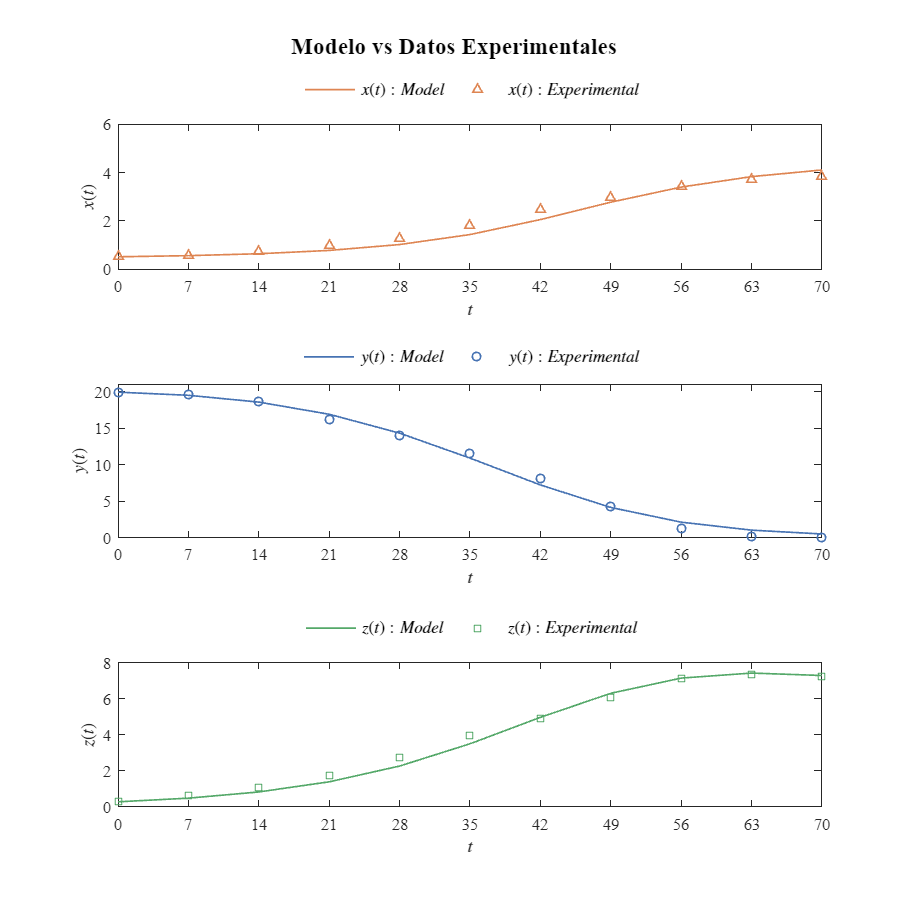

xm = reshape(mdl.Fitted, [N, 3]);
plotresults(to, data, xm); 
sgtitle('Modelo vs Datos Experimentales', 'FontName', 'Times New Roman', 'FontSize', 14, 'FontWeight', 'bold');
exportgraphics(gcf, 'results_subplots.pdf', 'ContentType', 'vector');

## Predicción a 2t

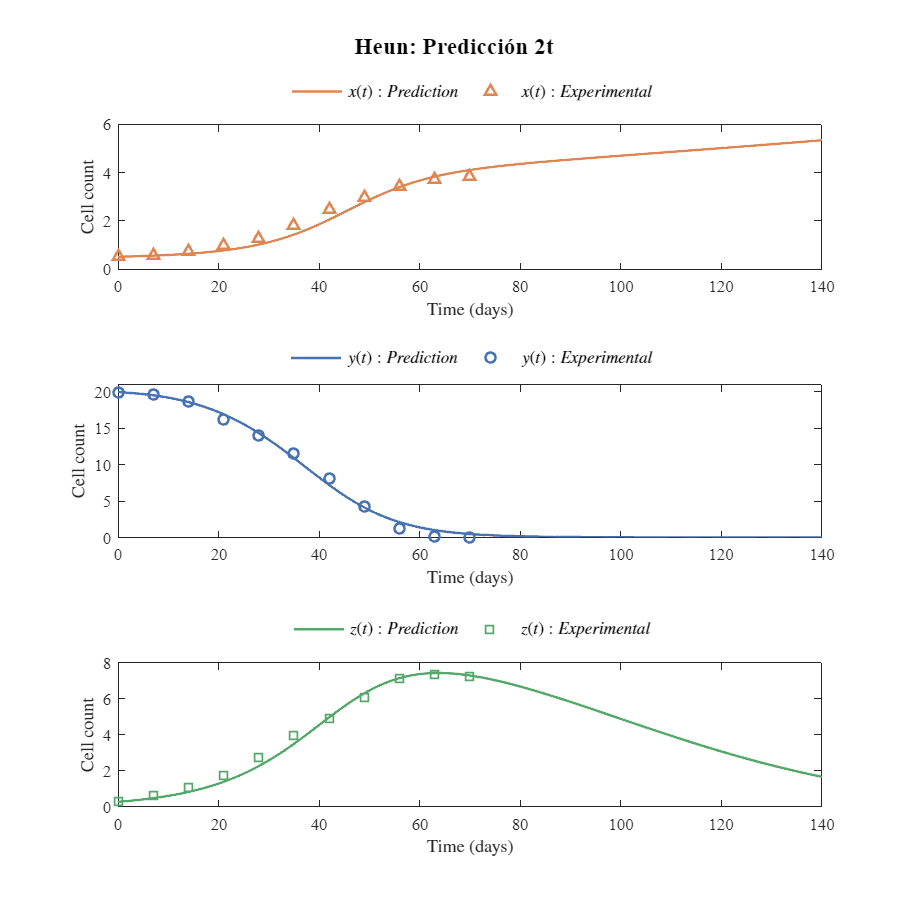

P = table2array(mdl.Coefficients(:,1)); 
x0 = xo(1); y0 = yo(1); z0 = zo(1);
tend = to(end);
dt = 0.1; 
[th, xn, yn, zn] = simulacion2t(x0, y0, z0, P, 2*tend, dt);
data_pred = [xn, yn, zn];
plot_prediccion(to, data, th, data_pred); 
sgtitle('Heun: Predicción 2t', 'FontName', 'Times New Roman', 'FontSize', 14, 'FontWeight', 'bold');
exportgraphics(gcf, 'data_heun_prediction.pdf', 'ContentType', 'vector');

## Puntos de equilibrio

clc; clear
syms x y z r1 r2 r3 r4 r5 r6
dx_dt = r1*x + r2*x*z*y == 0;
dy_dt = r3*y - r4*y*z == 0;
dz_dt = r5*z - r6*x*z == 0;
E= solve([dx_dt, dy_dt, dz_dt], [x,y,z]);
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(E.x))]);

Puntos de equilibrio del sistema: 2


for i=1:2
    disp([E.x(i); E.y(i); E.z(i)])
end

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} \frac{r_{5}}{r_{6}}\\ -\frac{r_{1}\,r_{4}}{r_{2}\,r_{3}}\\ \frac{r_{3}}{r_{4}} \end{array}\right)$$

## Matriz Jacobiana

dx_dt = r1*x + r2*x*z*y;
dy_dt = r3*y - r4*y*z;
dz_dt = r5*z - r6*x*z;

J=jacobian([ dx_dt, dy_dt, dz_dt], [x,y,z]);
fprintf('Matriz Jacobiana: \n'); disp(J)

Matriz Jacobiana: 


$$\left(\begin{array}{ccc} r_{1}+r_{2}\,y\,z & r_{2}\,x\,z & r_{2}\,x\,y\\ 0 & r_{3}-r_{4}\,z & -r_{4}\,y\\ -r_{6}\,z & 0 & r_{5}-r_{6}\,x \end{array}\right)$$

clc; clear; close all; warning('off')
r1 = 0.00656; r2 = 0.00095; r3 = 0.002211; r4 = 0.0122; r5 = 0.0937; r6 = 0.0247;
par = [r1;r2;r3;r4;r5;r6];
dt = 1E-3; tend = 1000;
E = equilibria(par);

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
eq2        ( 3.794e+00 ,-3.810e+01 , 1.812e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        +2.2e-03+0.0e+00i +6.6e-03+0.0e+00i +9.4e-02+0.0e+00i unstable  
eq2        -2.6e-02+0.0e+00i +2.4e-02+0.0e+00i +2.2e-03+0.0e+00i unstable  


## Simulink

clear; close all
param_control = false;
smooth = false; normalize = false;
[to,xo,yo,zo] = getdata2('datos_sistemas_biologicos.csv',smooth,normalize);
r1 = 0.00656; r2 = 0.00095; r3 = 0.002211; r4 = 0.0122; r5 = 0.0937; r6 = 0.0247;
par = [r1;r2;r3;r4;r5;r6];
mdl = eureqa(to, xo, yo, zo, par);

Cantidad de datos (n):          33
Cantidad de parámetros (k):     6
Grados de libertad (DFE):       27
Significancia (alpha):          0.05
Valor t-student:                2.0518
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate         SE           MoE                  CI95                 Pvalue  
    __________    _________    __________    _________    __________________________    __________

      {'r1'}      0.0031143      0.011477     0.023549      -0.020434       0.026663       0.78818
      {'r2'}      0.0012695    0.00050904    0.0010445     0.00022501       0.002314      0.019059
      {'r3'}      0.0022999      0.001164    0.0023884    -8.8527e-05      0.0046882      0.058482
      {'r4'}       0.014472    0.00099906   

E = equilibria(par);

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
eq2        ( 3.794e+00 ,-3.810e+01 , 1.812e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        +2.2e-03+0.0e+00i +6.6e-03+0.0e+00i +9.4e-02+0.0e+00i unstable  
eq2        -2.6e-02+0.0e+00i +2.4e-02+0.0e+00i +2.2e-03+0.0e+00i unstable  


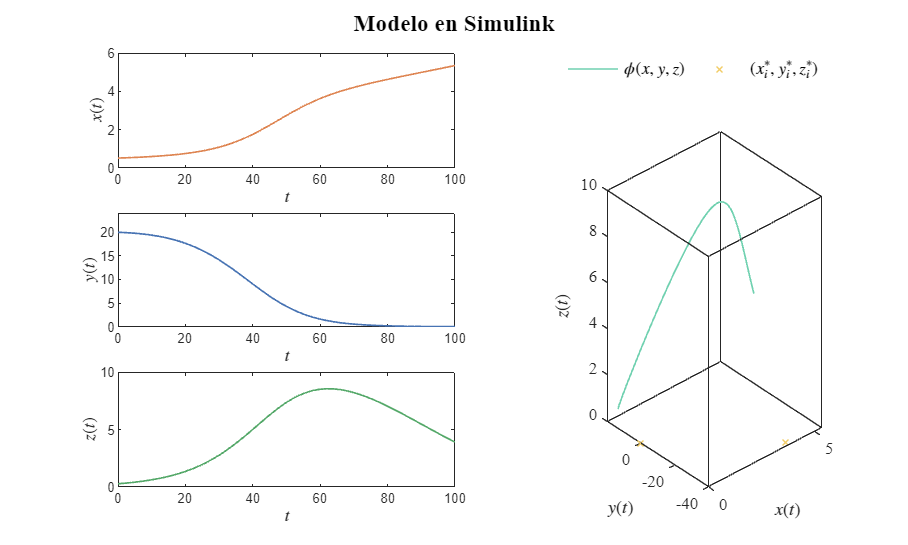

P = table2array(mdl.Coefficients(:,1));
file = 'modelo';
sim(file);
parameters.StopTime = '100';
parameters.Solver = 'ode45';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotEDOs(f.t, f.x, f.y, f.z,E,param_control);
sgtitle('Modelo en Simulink', 'FontName', 'Times New Roman', 'FontSize', 14, 'FontWeight', 'bold');
exportgraphics(gcf, 'modelo_simulink.pdf', 'ContentType', 'vector');

## Parámetro de control

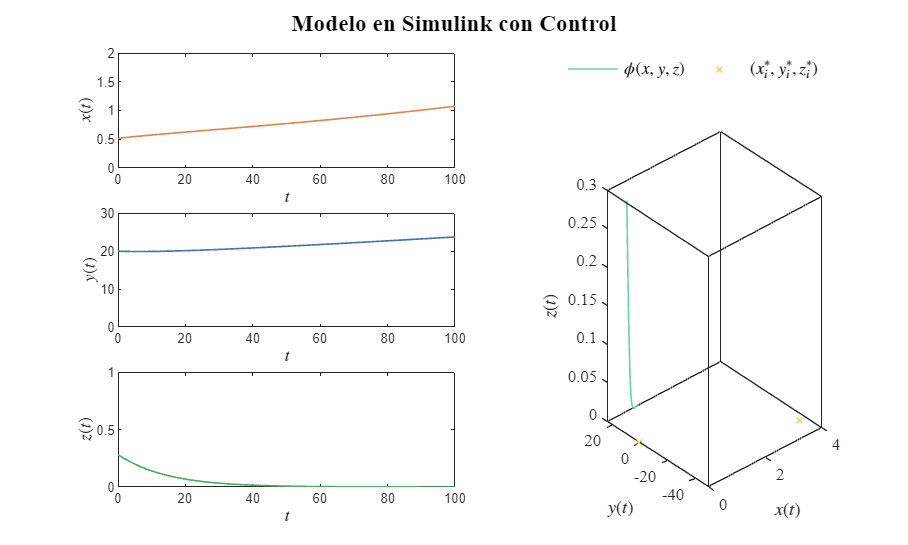

param_control = true;
smooth = false; normalize = false;
file2 = 'control';
sim(file2);
parameters.StopTime = '100';
parameters.Solver = 'ode45';
% parameters.MaxStep = '0.1';
f2 = sim(file2,parameters);
plotEDOs(f2.t, f2.x, f2.y, f2.z,E, param_control);
sgtitle('Modelo en Simulink con Control', 'FontName', 'Times New Roman', 'FontSize', 14, 'FontWeight', 'bold');
exportgraphics(gcf, 'control.pdf', 'ContentType', 'vector');

## Comparación Modelo Vs Control

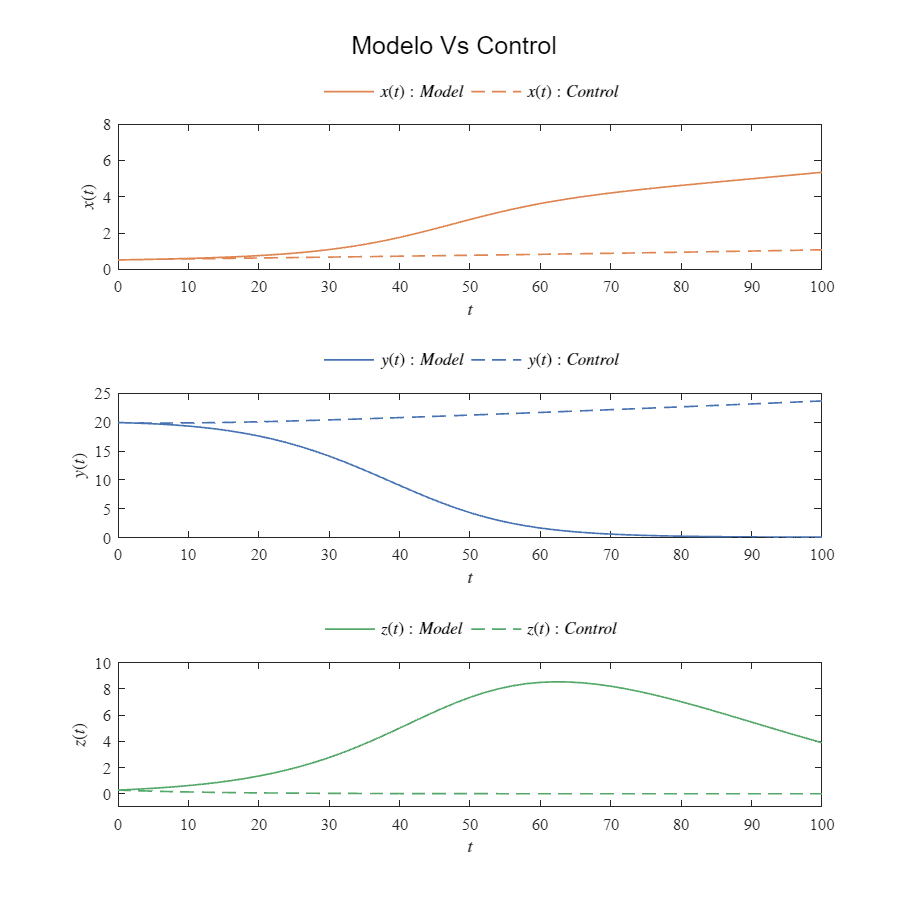

plotcomparacion(f.t,[f.x,f2.x],[f.y,f2.y],[f.z,f2.z]); sgtitle('Modelo Vs Control');...
    exportgraphics(gcf,'modelvscontrol.pdf','ContentType','vector')

## Funciones

### Soluciones y trayectoria en el plano de fase

function plotsys(t,x1,y1,z1,x2,y2,z2,x3,y3,z3)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,24,12])
    subplot(3,3,1)
    hold on, box on; grid off;
    plot(t,x1,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x_1(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,2)
    hold on, box on; grid off;
    plot(t,y1,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y_1(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,3)
    hold on, box on; grid off;
    plot(t,z1,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$z_1(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(3,3,4)
    hold on, box on; grid off;
    plot(t,x2,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x_2(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,5)
    hold on, box on; grid off;
    plot(t,y2,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y_2(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,6)
    hold on, box on; grid off;
    plot(t,z2,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$z_2(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,3,7)
    hold on, box on; grid off;
    plot(t,x3,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x_3(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,8)
    hold on, box on; grid off;
    plot(t,y3,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y_3(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,3,9)
    hold on, box on; grid off;
    plot(t,z3,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$z_3(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function plotsys2(to,xo,yo,zo)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,24,12])
    subplot(3,1,1)
    hold on, box on; grid off;
    plot(to,xo,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,1,2)
    hold on, box on; grid off;
    plot(to,yo,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(3,1,3)
    hold on, box on; grid off;
    plot(to,zo,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    
end

function plotresults(t, data, xp)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1 1 25 25])
    FS = 10;
    b = [0.28, 0.45, 0.70]; 
    n = [0.87, 0.52, 0.32]; 
    v = [0.33, 0.66, 0.41]; 
    subplot(3,1,1); box on; hold on; grid off;
    
    plot(t, xp(:,1), '-', t, data(:,1), '^','LineWidth', 1, 'Color', n, 'MarkerSize', 5);
    L = legend('$x(t): Model$', '$x(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 6]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off

    subplot(3,1,2); box on; hold on; grid off;
    plot(t, xp(:,2), '-', t, data(:,2), 'o','LineWidth', 1, 'Color', b, 'MarkerSize', 5);
    L = legend('$y(t): Model$', '$y(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 21]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;

    subplot(3,1,3); box on; hold on; grid off;
    plot(t, xp(:,3), '-', t, data(:,3), 's','LineWidth', 1, 'Color', v, 'MarkerSize', 5);
    L = legend('$z(t): Model$', '$z(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 8]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;
end

function plotcomparacion(t,x,y,z)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1 1 25 25])
    FS = 10;
    b = [0.28, 0.45, 0.70]; 
    n = [0.87, 0.52, 0.32]; 
    v = [0.33, 0.66, 0.41]; 
    subplot(3,1,1); box on; hold on; grid off;
    
    plot(t, x(:,1), '-', t, x(:,2), '--','LineWidth', 1, 'Color', n, 'MarkerSize', 5);
    L = legend('$x(t): Model$', '$x(t): Control$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 8]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off

    subplot(3,1,2); box on; hold on; grid off;
    plot(t, y(:,1), '-', t, y(:,2), '--','LineWidth', 1, 'Color', b, 'MarkerSize', 5);
    L = legend('$y(t): Model$', '$y(t): Control$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 25]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;

    subplot(3,1,3); box on; hold on; grid off;
    plot(t, z(:,1), '-', t, z(:,2), '--','LineWidth', 1, 'Color', v, 'MarkerSize', 5);
    L = legend('$z(t): Model$', '$z(t): Control$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('$t$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 10]); yticks(0:2:10)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;
end

### Ajuste por regresión no lineal

function mdl = eureqa(to,xo,yo,zo,par)
    to = to(:); xo = xo(:); yo = yo(:); zo = zo(:);
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    t = [to;to;to];
    fo = [xo;yo;zo];
    
    function fa = model(par,ta)
        r1 = par(1); r2 = par(2); r3 = par(3); r4 = par(4); r5 = par(5); r6 = par(6);
        dt = 1E-1;
        time = (0:dt:max(ta))';
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        z = zeros(length(time),1); z(1) = z0;
        n = round(max(ta)/dt);
        
        for i = 1:n %Método de diferencias finitas
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = r1*x + r2*x*z*y;
            dy = r3*y - r4*y*z;
            dz = r5*z - r6*x*z;
        end

        xi = interp1(time,x,to,'linear');
        yi = interp1(time,y,to,'linear');
        zi = interp1(time,z,to,'linear');

        fa = [xi;yi;zi];
    end

    mdl = fitnlm(t,fo,@model,par);
    Parameters = {'r1'; 'r2'; 'r3'; 'r4'; 'r5';'r6'};
    biostats(mdl, Parameters);
end

function [th, xh, yh, zh] = simulacion2t(x0, y0, z0, par, tend, dt)
    r1 = par(1); r2 = par(2); r3 = par(3); r4 = par(4); r5 = par(5); r6 = par(6);
    th = (0:dt:tend)';
    n = length(th) - 1;
  
    xh = zeros(n+1, 1); xh(1) = x0;
    yh = zeros(n+1, 1); yh(1) = y0;
    zh = zeros(n+1, 1); zh(1) = z0;
    
    for i = 1:n 
        fx = r1*xh(i) + r2*xh(i)*zh(i)*yh(i);
        fy = r3*yh(i) - r4*yh(i)*zh(i);
        fz = r5*zh(i) - r6*xh(i)*zh(i);
        
        xn = xh(i) + fx*dt;
        yn = yh(i) + fy*dt;
        zn = zh(i) + fz*dt;
        
        fxn = r1*xn + r2*xn*zn*yn;
        fyn = r3*yn - r4*yn*zn;
        fzn = r5*zn - r6*xn*zn;
        
        xh(i+1) = xh(i) + (fx + fxn)*dt/2;
        yh(i+1) = yh(i) + (fy + fyn)*dt/2;
        zh(i+1) = zh(i) + (fz + fzn)*dt/2;
    end
end

### Datos experimentales

function [t,x1,y1,z1,x2,y2,z2,x3,y3,z3] = getdata(file)
    sys = readmatrix(file);
    t = round(sys(:,1));
    x1 = sys(:,2); 
    y1 = sys(:,3);
    z1 = sys(:,4);
    x2 = sys(:,5); 
    y2 = sys(:,6);
    z2 = sys(:,7);
    x3 = sys(:,8); 
    y3 = sys(:,9);
    z3 = sys(:,10);
    return

end

function [to,xo,yo,zo] = getdata2(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    xo = sys(:,5); 
    yo = sys(:,6);
    zo = sys(:,7);
    if smooth == false && normalize == false
    return
    elseif smooth == true && normalize == false
    xo = smoothdata(xo,'gaussian',5); xo = xo/max(xo);
    yo = smoothdata(yo,'gaussian',5); yo = yo/max(yo);
    zo = smoothdata(zo,'gaussian',5); zo = zo/max(zo);
    elseif smooth == false && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    zo = zo/max(zo);
    elseif smooth == true && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    zo = zo/max(zo);
    xo = smoothdata(xo,'gaussian',5); xo = xo/max(xo);
    yo = smoothdata(yo,'gaussian',5); yo = yo/max(yo);
    zo = smoothdata(zo,'gaussian',5); zo = zo/max(zo);
    end
end

## Funciones

### Parámetros y condiciones iniciales

function biostats(mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    n_datos = mdl.NumObservations;      
    n_params = mdl.NumCoefficients;     
    dof = mdl.DFE;                      
    tval = tinv(1 - alpha/2, dof);     
    MoE = SE * tval;                    
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    R2o = mdl.Rsquared.Ordinary;        
    SSE = mdl.SSE;                      
    AICc = mdl.ModelCriterion.AICc;
    
    fprintf('Cantidad de datos (n):          %d\n', n_datos);
    fprintf('Cantidad de parámetros (k):     %d\n', n_params);
    fprintf('Grados de libertad (DFE):       %d\n', dof);
    fprintf('Significancia (alpha):          %.2f\n', alpha);
    fprintf('Valor t-student:                %.4f\n', tval);
    disp('-------------------------------------------------------------');
    disp('Coefficients:');
    disp(Results);
    disp('-------------------------------------------------------------');
    disp('Bondad de Ajuste:');
    fprintf('R-cuadrada ordinaria:           %.4f\n', R2o);
    fprintf('Suma residual de cuadrados:     %.4f\n', SSE);
    fprintf('Criterio de inf. Akaike (AICc): %.4f\n', AICc);
    disp('=============================================================');
end



function plot_prediccion(to, data_exp, th, data_pred)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1 1 25 25])
    FS = 10;
    b = [0.28, 0.45, 0.70]; 
    n = [0.87, 0.52, 0.32]; 
    v = [0.33, 0.66, 0.41]; 

    subplot(3,1,1); box on; hold on; grid off;
    plot(th, data_pred(:,1), '-', to, data_exp(:,1), '^', ...
        'LineWidth', 1.5, 'Color', n, 'MarkerSize', 6); 
    L = legend('$x(t): Prediction$', '$x(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cell count', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 max(th)]); 
    ylim([0 6]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;

    subplot(3,1,2); box on; hold on; grid off;
    
    plot(th, data_pred(:,2), '-', to, data_exp(:,2), 'o', ...
        'LineWidth', 1.5, 'Color', b, 'MarkerSize', 6);
    L = legend('$y(t): Prediction$', '$y(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cell count', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 max(th)]);
    ylim([0 21]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;

    subplot(3,1,3); box on; hold on; grid off;
    plot(th, data_pred(:,3), '-', to, data_exp(:,3), 's', ...
        'LineWidth', 1.5, 'Color', v, 'MarkerSize', 6);
    L = legend('$z(t): Prediction$', '$z(t): Experimental$');
    set(L, 'Interpreter', 'Latex', 'Fontsize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal')
    xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cell count', 'Interpreter', 'latex', 'FontSize', FS)
    xlim([0 max(th)]);
    ylim([0 8]); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold off;
end

function plotEDOs(t,x,y,z,E,control)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 15])
    FS = 10;
    b = [0.28, 0.45, 0.70]; 
    n = [0.87, 0.52, 0.32]; 
    v = [0.33, 0.66, 0.41];
    vm  = [0.44, 0.82, 0.69]; 
    am = [0.95, 0.80, 0.40];
    
    if control == false
    subplot(3,6,[1 2 3]); box on; hold on;
    plot(t,x,'-','LineWidth',1,'Color',n)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 6])

    subplot(3,6,[7 8 9]); box on; hold on;
    plot(t,y,'-','LineWidth',1,'Color',b)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 24])

    subplot(3,6,[13 14 15]); box on; hold on;
    plot(t,z,'-','LineWidth',1,'Color',v)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 10])

    subplot(3,6,[5 6 11 12 17 18]); hold on; grid off; box on; view([-42 21])
    ax = gca; ax.BoxStyle = 'full';
    plot3(x,y,z,'-','LineWidth',1,'Color',vm)
    plot(E(:,1),E(:,2),'x','MarkerSize',5,'LineWidth',1,'Color',am)
    L = legend('$\phi(x,y,z)$','$(x^*_i,y^*_i,z^*_i)$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    zlabel('$z(t)$','Interpreter','latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    else
    
    subplot(3,6,[1 2 3]); box on; hold on;
    plot(t,x,'-','LineWidth',1,'Color',n)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 2])

    subplot(3,6,[7 8 9]); box on; hold on;
    plot(t,y,'-','LineWidth',1,'Color',b)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 30])


    subplot(3,6,[13 14 15]); box on; hold on;
    plot(t,z,'-','LineWidth',1,'Color',v)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    ylim([0 1])


    subplot(3,6,[5 6 11 12 17 18]); hold on; grid off; box on; view([-42 21])
    ax = gca; ax.BoxStyle = 'full';
    plot3(x,y,z,'-','LineWidth',1,'Color',vm)
    plot(E(:,1),E(:,2),'x','MarkerSize',5,'LineWidth',1,'Color',am)
    L = legend('$\phi(x,y,z)$','$(x^*_i,y^*_i,z^*_i)$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    zlabel('$z(t)$','Interpreter','latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    end
    
end


### Equilibrios

function [E,lambda] = equilibria(par)
    r1 = par(1); r2 = par(2); r3 = par(3); r4 = par(4); r5 = par(5); r6 = par(6);
    
    e1 = [0; 0; 0];
    e2 = [r5/r6; -(r1*r4)/(r2*r3); r3/r4];
    
    E = [e1, e2]; E = double(E)'; E(E>-1e-12 & E<1e-12) = 0;
    
    names = {'eq1'; 'eq2'};
    
    num_eq = size(E, 1); 
    
    fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria', ' x*', ' y*', ' z*');
    fprintf('-------------------------------------------------\n');
    for i = 1:num_eq
        fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
    end
    
    x = E(:,1); y = E(:,2); z = E(:,3); 
    lr = zeros(num_eq,3); li = zeros(num_eq,3); stability = cell(num_eq,1);
    
    for i = 1:num_eq
        xi = x(i);
        yi = y(i);
        zi = z(i);
        
        J = [r1 + r2*yi*zi, r2*xi*zi, r2*xi*yi;
            0, r3 - r4*zi, -r4*yi;
            -r6*zi, 0, r5 - r6*xi];
        
        lr(i,:) = real(eig(J)); lr(lr>-1e-12 & lr<1e-12) = 0;
        li(i,:) = imag(eig(J));
        
        if all(lr(i,:) < 0)
            stability{i,1} = 'stable';
        elseif any(lr(i,:) > 0)
            stability{i,1} = 'unstable';
        else
            stability{i,1} = 'unidentified';
        end
    end
    
    lambda = lr + 1i*li;
    
    fprintf('\n\n%-10s | %-16s | %-16s | %-16s| %-10s|\n','Equilibria', ' lambda 1', ' lambda 2', ' lambda 3', 'stability');
    fprintf('---------------------------------------------------------------------------------\n');
    for i = 1:num_eq
        fprintf('%-10s %+.1e%+.1ei %+.1e%+.1ei %+.1e%+.1ei %-10s\n', names{i}, real(lambda(i,1)),imag(lambda(i,1)), ...
        real(lambda(i,2)),imag(lambda(i,2)), real(lambda(i,3)),imag(lambda(i,3)), stability{i});
    end
end